M130 Lab 4

Start by checking the image properties of your assigned image and loading it into MATLAB

%%Read image and check basic image properties
info = imfinfo('Image_2.tif');
%Note how this time info is actually an array with 35 entries, this is
%becuse the multidimensional.tif file contains a 3D image with 35 planes
length(info)

ans = 190

%Remember to use imfinfo to see what the image size is
info(1).Width

ans = 213

info(1).Height

ans = 313

info(1).Height

ans = 313

info(1).BitDepth

ans = 16

info(1).ColorType

ans = 'grayscale'

disp("The size of the image is 313x213, with 190 pages")

The size of the image is 313x213, with 190 pages


%create the placeholder variable with 'zeros' and use a 
img = zeros(info(1).Height,info(1).Width,length(info),'uint16');
%for loop to read in the data
for i = 1:length(info)
    img(:,:,i) = imread('Image_2.tif',i);
end

size(img)

ans =    313   213   190


max(img(:))

ans = uint16
1390

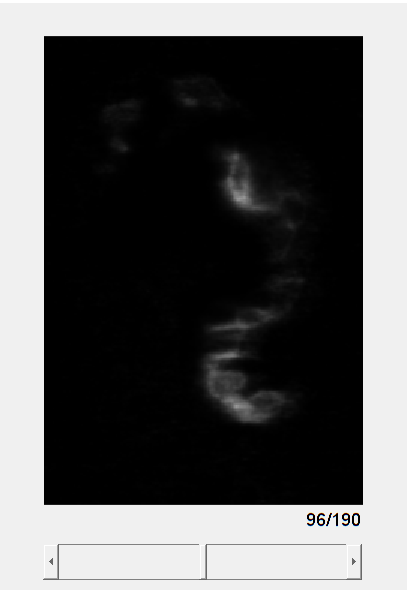

ans =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 96
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 1390]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


%Compute a max projection of your image and display it (1 point)
max_proj = max(img,[],3);
figure(1);
imagesc(max_proj,[0,1390])
colormap gray 
axis image
colorbar

sliceViewer(img, "DisplayRange", [0,1390])

%sliceViewer(img) 
% seems to be just a single blob on page 190

%Compute the Fourier Transform of your max projection image and display the
%real values of the Fourier Transform
%Remember that the FT image has to be rearranged to display correctly using
%the fftshift command    (2 point)

ft_image = fft2(max_proj); 
shift_ft_image = fftshift(ft_image); 
disp('for better visualization, shift 0-frequency component to the center')

for better visualization, shift 0-frequency component to the center


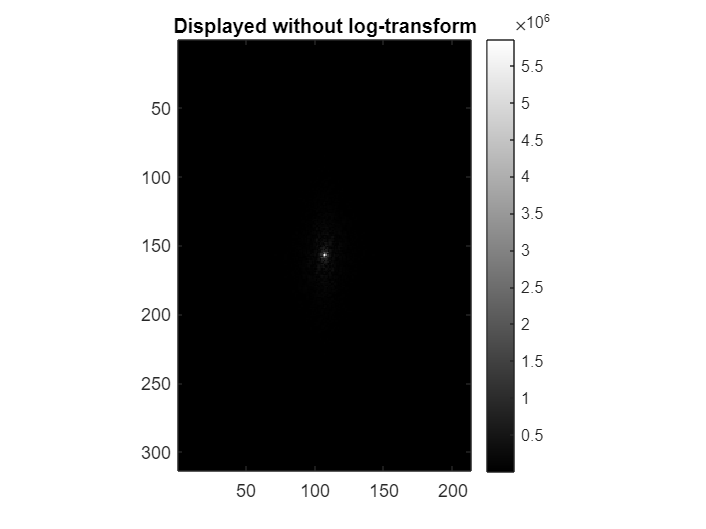

figure
imagesc(abs(shift_ft_image))

colormap gray
axis image
colorbar
title("Displayed without log-transform")

disp("We notice a single bright dot at 100x150")

We notice a single bright dot at 100x150


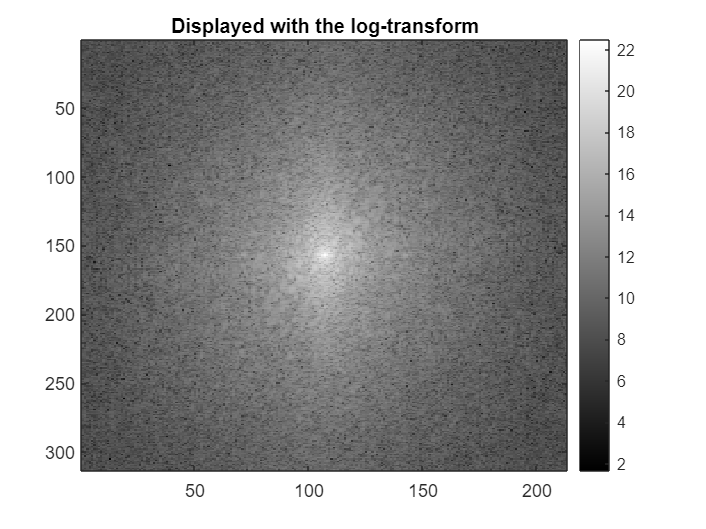

figure 
imagesc(log2(1+abs(shift_ft_image)))
colorbar
colormap gray
title("Displayed with the log-transform")


% choosing low frequency region of image, set to zero. 
% we find the center and choose the region around the center
% to be made zero

alongY = 10;
alongX = 10;
centerY = uint16(size(max_proj,1)/2) 

centerY = uint16
157

centerX = uint16(size(max_proj,2)/2) 

centerX = uint16
107

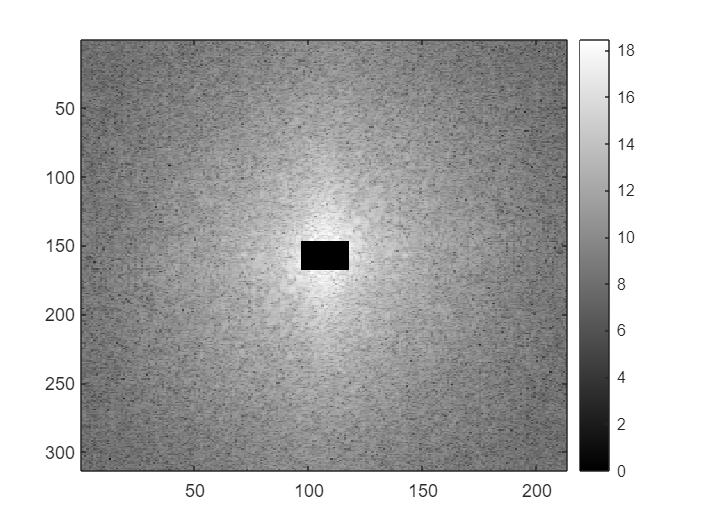

low_freq_del_image = shift_ft_image;

for i =(centerY-alongY):(centerY+alongY)
    for j = (centerX-alongX):(centerX+alongX)
        low_freq_del_image(i,j) = 0;
    end
end
imagesc(log2(1+abs(low_freq_del_image)))
colorbar
colormap gray

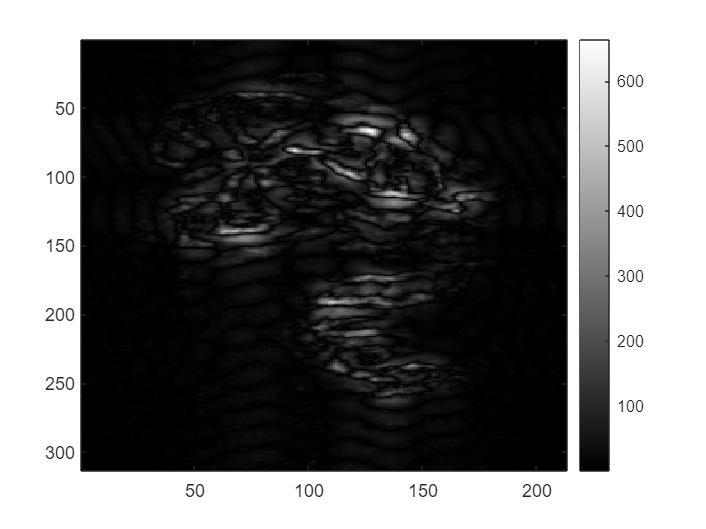

%Calculating iff2 of the low frequency values, 
%or taking the inverse fourier transform using iff2
new_img = ifft2(ifftshift(low_freq_del_image));
imagesc(abs(new_img))
colormap gray
colorbar

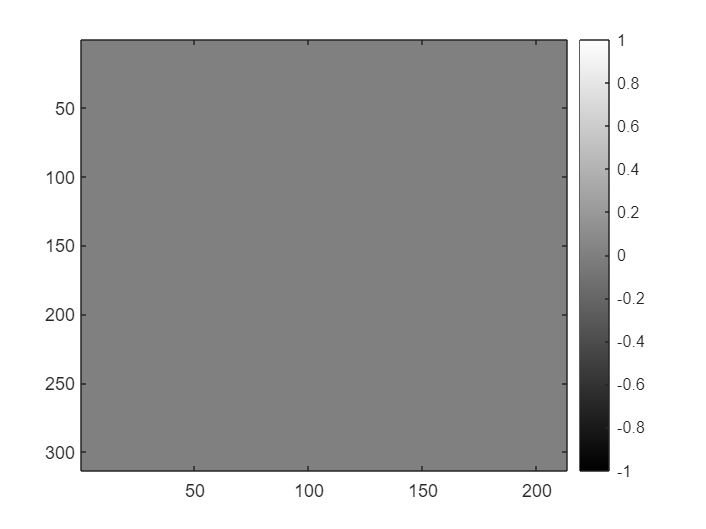

% now onto the high-frequency images 
high_freq_del_image = shift_ft_image;
high_freq_del_image(1:100,:) = 0;
high_freq_del_image(end-100:end,:)=0;
high_freq_del_image(:,1:150) = 0;
high_freq_del_image(:,end-150:end) = 0;
imagesc(log2(1+abs(high_freq_del_image)))
colorbar


% Calculate iff2 for high frequency values
new_img = ifft2(ifftshift(low_freq_del_image));
imagesc(abs(new_img))
colormap gray
colorbar

high_freq_del_image = shift_ft_image;
high_freq_del_image(1:100,:) = 0;
high_freq_del_image(end-100:end,:)=0;
high_freq_del_image(:,1:150) = 0;
high_freq_del_image(:,end-150:end) = 0;
imagesc(log2(1+abs(high_freq_del_image)))
colorbar

% Calculating ifft2 of the same 
new_img = ifft2(ifftshift(high_freq_del_image));
imagesc(abs(new_img))
colormap gray
colorbar

%Applying Gaussian over the image 
% 1- define Gaussain filter 
% make the filter of any size, 
m = 20;
n = 20;
gaussian = zeros(m,n);
c = 3; % choosing c for the filter 
disp(['Here I am choosing 7 because I have chosen a blob ' ...
    'and found its pixel width and length to be 40x40, ' ...
    'and then I divide that number by 6. We can set the c to be that value.'])

Here I am choosing 7 because I have chosen a blob and found its pixel width and length to be 40x40, and then I divide that number by 6. We can set the c to be that value.


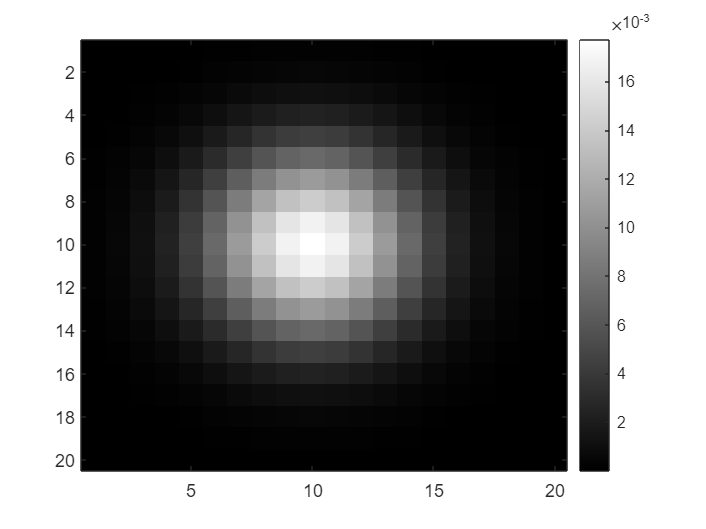

for x=1:n
    for y=1:m
        sq_dist = (x-n/2)^2 + (y-m/2)^2; % distance from the center pixel
        gaussian(y,x) = exp(-1*sq_dist/(2*c*c)); % division by the standard deviation.
    end
end
gaussian = gaussian./sum(gaussian(:)); % to normalize the kernel since we are taking discrete values. 
imagesc(gaussian)
colormap gray
colorbar

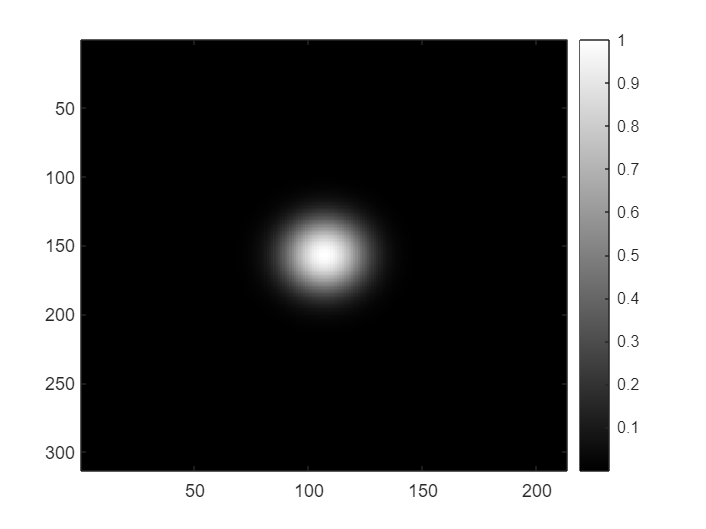

ft_gauss = fft2(gaussian, size(max_proj,1),size(max_proj,2));
shift_ft_gauss = fftshift(ft_gauss);
imagesc(log2(1+abs(shift_ft_gauss)))
colorbar

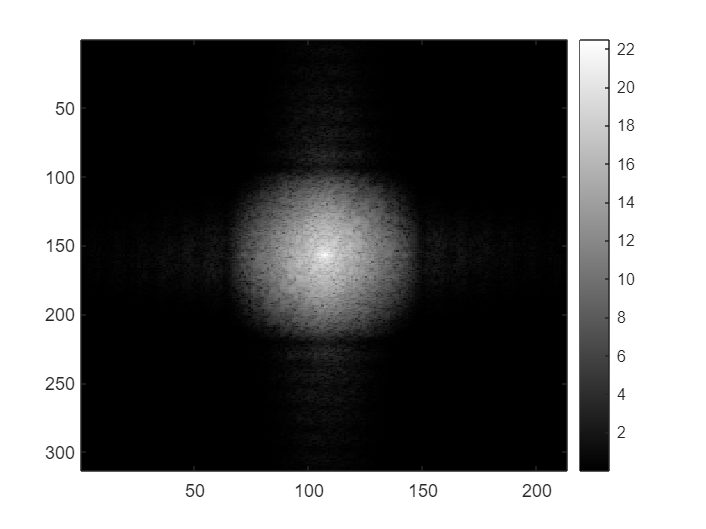

% Apply Gaussian filter over image, and see image in frequency domain. 
filtered_ft_img = shift_ft_image.*shift_ft_gauss; 
imagesc(log2(1+abs(filtered_ft_img)))
colorbar

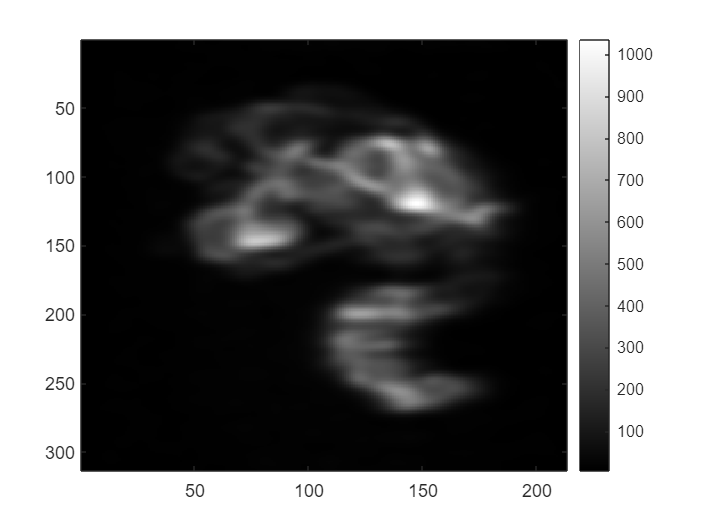

% Computing inverse fft of the image 
new_img = ifft2(ifftshift(filtered_ft_img)); 
imagesc(abs(new_img))
colormap gray 
colorbar

Compare your image and its Fourier Transform. Are there any features of your image that you can see reflected in the Fourier Transform? Think specifically about the orientation of objects in the image, and of the presence or absence of directional edges in the image. Type your observations here (2 points):

My image originally from max_proj has a little bit of faint dots around the bottom left corner and a particular discernable bright blob around 100x100 pixels. The fourier transformed image is different in that, there seem to be more lineages (vertical or horizontal lines) after the gaussian filter has been applied to it. The orientation of the objects in the image has not changed, the coordinates still match up. 

The reason we use a Gaussian filter is to make a weighted average image. We do this by computing a Gaussian of desired width, compute the Fourier Transform of that Gaussian, compute the Fourier Transform of the image, multiply the two FT together (by convolution?), and compute the Inverse Fourier Transform of the product. 

I see that, after adopting the Gaussian filter, we have reduced the high frequencies noise, but at an advent we are blurring sharp edges in the image. The directional edges are enhanced with low frequencies being set to zero. With high frequencies being set to zero, we have reduced noise. 

Did the value for c that you picked do a good job? Is the image too blurred? Noise not reduced enough? How would you adjust the value of c to get better results, if needed (1 pts) 

The value for c that I picked was 3 because I have identified a blob at 150x120 pixels and I roughly estimated that its size is 20 by 20, and dividing 20 by 6 gives me an integer c value of 3. This blob is valid because it is solid rather than hollow. The noise is reduced enough, almost to the point of blurring the actual image itself. I think lowering the c value would be better because I tried and it did not blur the image as much and retained more features. 

m = 10

n = 10 

c = 1 

Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most? (1 point)

So far, everything seems to be working fine. I would be benefited from reviewing the definition of "gradient operations" again in lecture. 